# Adding Measurement Noise to Raw Data and Data with Sensor Faults

load workspace_c.mat

cut_seg = ceil(0.5*NumSeg);
IntData = []; % including all events, sensor faults and noise

## 1 Add Noise

for i = 1:NumSeg
    for j = 1:nDOF
        for m = 1:NumEventType
            for n = 1:NumFaultType
                if i < cut_seg
                    IntData(i,j,m,n,:) = squeeze(Data_Fault(i,j,m,n,:));
                else
                    IntData(i,j,m,n,:) = AddNsByNsFloor(squeeze(Data_Fault(i,j,m,n,:)),ns_level);%(rand(1)-1)*2*ns_level);
                end
            end
        end
    end
end

fn_tmp = 'IntData.mat';
save(fn_tmp,'IntData') 


% check data
indi = randi(NumSeg/2) + cut_seg

indi = 7

indj = randi(nDOF)

indj = 5

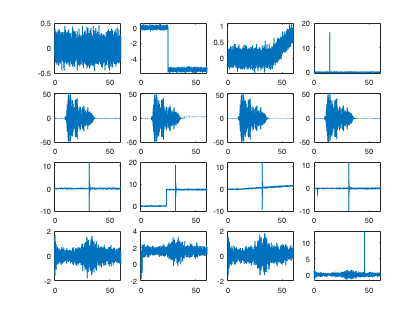


% plot
for m = 1:NumEventType
    for n = 1:NumFaultType
        %disp((m-1)*NumFaultType+n)
        subplot(NumEventType,NumFaultType,(m-1)*NumFaultType + n)
        plot(TimeSeries,squeeze(IntData(indi,indj,m,n,:)))
    end
end

## 2 Prepare for Training & Label Preparation

### 2.1 by Event

Data_by_Event = [];
Data_by_Event_PT = [];
Label_by_Event = [];
Label_by_Event_PT = [];


for m = 1:NumEventType
    for n = 1:NumFaultType
        for i = 1:NumSeg
            for j = 1:nDOF
                tmp_ind =  (m-1)*NumFaultType*NumSeg*nDOF + (n-1)*NumSeg*nDOF + (i-1)*nDOF + j;
                Data_by_Event{tmp_ind} = squeeze(IntData(i,j,m,n,:));
                Data_by_Event_PT(:,tmp_ind) = squeeze(IntData(i,j,m,n,:));
                if m == 1
                    Label_by_Event{tmp_ind} = 'av';% ambient vibration
                    Label_by_Event_PT(tmp_ind) = 1;
                elseif m == 2
                    Label_by_Event{tmp_ind} = 'eq';% earthquake
                    Label_by_Event_PT(tmp_ind) = 2;
                elseif m == 3
                    Label_by_Event{tmp_ind} = 'ip';% impact
                    Label_by_Event_PT(tmp_ind) = 3;
                else
                    Label_by_Event{tmp_ind} = 'wd';% strong wind
                    Label_by_Event_PT(tmp_ind) = 4;
                end
            end
        end
    end
end

disp('Data_by_Event integration finished!')

Data_by_Event integration finished!



fn_tmp = 'Data_by_Event.mat';
save(fn_tmp,'Data_by_Event') 

fn_tmp = 'Data_by_Event_PT.mat';
save(fn_tmp,'Data_by_Event_PT') 

fn_tmp = 'Label_by_Event_PT.mat';
save(fn_tmp,'Label_by_Event_PT') 


### 2.2 by Sensor Fault

Data_by_Fault = [];
Data_by_Fault_PT = [];
Label_by_Fault = [];
Label_by_Fault_PT = [];

for n = 1:NumFaultType
    for m = 1:NumEventType
        for i = 1:NumSeg
            for j = 1:nDOF
                tmp_ind =  (n-1)*NumEventType*NumSeg*nDOF + (m-1)*NumSeg*nDOF + (i-1)*nDOF + j;
                Data_by_Fault{tmp_ind} = squeeze(IntData(i,j,m,n,:));
                Data_by_Fault_PT(:,tmp_ind) = squeeze(IntData(i,j,m,n,:));
                if n == 1
                    Label_by_Fault{tmp_ind} = 'f';% fault free
                    Label_by_Fault_PT(tmp_ind) = 1;
                elseif n == 2
                    Label_by_Fault{tmp_ind} = 'b';% bias
                    Label_by_Fault_PT(tmp_ind) = 2;
                elseif n == 3
                    Label_by_Fault{tmp_ind} = 'd';% drift
                    Label_by_Fault_PT(tmp_ind) = 3;
                else
                    Label_by_Fault{tmp_ind} = 's';% spike
                    Label_by_Fault_PT(tmp_ind) = 4;
                end
            end
        end
    end
end

disp('Data_by_Fault integration finished!')

Data_by_Fault integration finished!



fn_tmp = 'Data_by_Fault_PT.mat';
save(fn_tmp,'Data_by_Fault_PT') 

fn_tmp = 'Label_by_Fault_PT.mat';
save(fn_tmp,'Label_by_Fault_PT') 

### 2.3 by Event & Fault

Data_Event_Fault = Data_by_Event;

Data_Event_Fault_PT = Data_by_Event_PT;

Label_Event_Fault = [];

Label_Event_Fault_PT = [];

for m = 1:NumEventType
    for n = 1:NumFaultType
        for k = 1:NumSeg*nDOF
            if m == 1
                tmp_event = 'av';
            elseif m == 2
                tmp_event = 'eq';
            elseif m == 3
                tmp_event = 'ip';
            else
                tmp_event = 'wd';
            end
            if n == 1
                tmp_fault = 'f';
            elseif n == 2
                tmp_fault = 'b';
            elseif n == 3
                tmp_fault = 'd';
            else
                tmp_fault = 's';
            end

            tmp_label = [tmp_event '_' tmp_fault];

            tmp_ind = (m-1)*NumFaultType*NumSeg*nDOF + (n-1)*NumSeg*nDOF + k;

            Label_Event_Fault{tmp_ind} = tmp_label;
        end
    end
end

for m = 1:NumEventType
    for n = 1:NumFaultType
        for k = 1:NumSeg*nDOF
            if m == 1
                tmp_event = 1;
            elseif m == 2
                tmp_event = 2;
            elseif m == 3
                tmp_event = 3;
            else
                tmp_event = 4;
            end
            if n == 1
                tmp_fault = 1;
            elseif n == 2
                tmp_fault = 2;
            elseif n == 3
                tmp_fault = 3;
            else
                tmp_fault = 4;
            end

            tmp_label = tmp_event*10 + tmp_fault;

            tmp_ind = (m-1)*NumFaultType*NumSeg*nDOF + (n-1)*NumSeg*nDOF + k;

            Label_Event_Fault_PT(tmp_ind) = tmp_label;
        end
    end
end

disp('Data_Event_Fault integration finished!')

Data_Event_Fault integration finished!



fn_tmp = 'Data_Event_Fault_PT.mat';
save(fn_tmp,'Data_Event_Fault_PT') 

fn_tmp = 'Label_Event_Fault_PT.mat';
save(fn_tmp,'Label_Event_Fault_PT') 


save workspace_d.mat